modified from program of Nina Angelica Zambale-Simon

#### Creates off-axis Gaussian beam for astrometric detection

close all

l =3.2;
% l=20 % uncomment this to play with more values of l

lambda = 633;       % 604, 612, 633 nm only. Chooses LUT for calibration.
w0 = 90;         % gaussian waist size pixels

## ------------------- DO NOT EDIT BELOW THIS POINT ----------------------- 

kx = 142;   %75     % k vector. Chosen for clearest separation between orders.
ky = 150;   %90
% INITIALIZE HOLOGRAM
px = 1920;          % image size (x axis)   
py = 1080;          % image size (y axis)
dp = 1;             % pixel size

[X,Y] = meshgrid(-px/2:px/2-dp,-py/2:dp:py/2-dp);   % defining image plane
R = sqrt(X.^2 + Y.^2);      % convert cartesian to polar coords (radius)

Phi = angle(X + 1i.*Y);     % convert cartesian to polar coords (azimuthal coordinate)
phase = l.*Phi;
circ = exp(-(R.^2)./(w0.^2));     % gaussian "aperture" overlaid on CGH


#### generate an image of the phase map

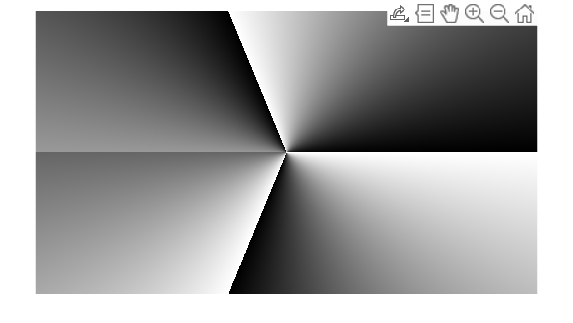

img_phase = mod(phase, 2*pi);                       % partition the azimuthal coord. by complete revolutions (i.e. multiples of 2 pi)
img_phase = img_phase ./ max(img_phase, [], 'all'); % normalize to 1
img_phase = 1 - img_phase;                          % reverse 0 to 1

figure(1)
imshow(img_phase);
colormap gray

next: animate the phase maps! (for slides presentation)

## CREATING THE HOLOGRAM

sz_hol = size(phase,1)*size(phase,2);

R = randperm(sz_hol);

% UNCOMMENT THE FF. when running the SLM!
% add_heds_path;
% heds_init_slm;
% heds_utils_slm_preview_show;

% for P1 = 1:-0.1:0

RUN AT THIS POINT

P1 = 1; %amt of information retained
P = 1 - P1; %percentage

R_indx = R(1:round(P*sz_hol));

for i = 1:numel(R_indx)
    phase(R_indx(i)) = 0;
end

u_LG = exp(-1i.*phase) + exp(1i.*(kx.*X+ky.*Y));     % sum of LG and plane wave
hol = u_LG.*conj(u_LG).*double(circ);       % calculates intensity, applies gaussian "aperture"
hol = 255.*hol./max(max(hol));      % normalize to max gray value of 255


### APPLY CALIBRATION

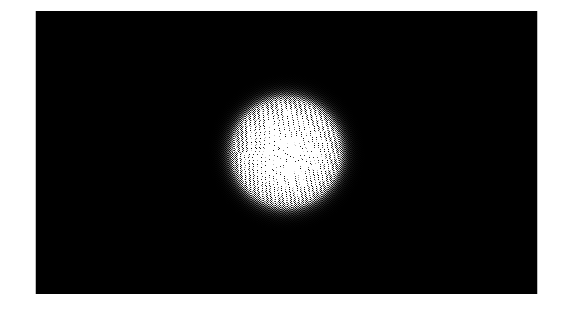

method = 'moving';  % choose which LUT to apply.
lut = uint8(csvread([num2str(lambda) '_' method '.csv']))';    % load LUT
hol_lut = intlut(uint8(hol),lut);           % apply LUT to hologram

figure(2)
imshow(hol)

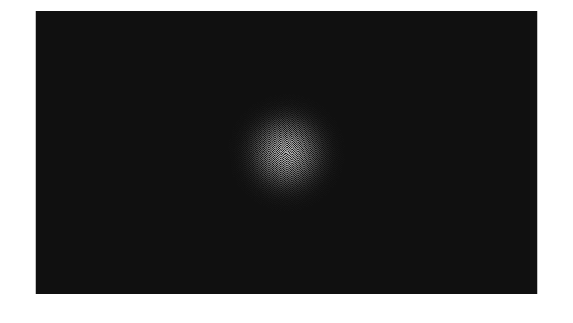

imshow(uint8(hol_lut));
colormap gray

% heds_show_data(uint8(hol_lut));


% end